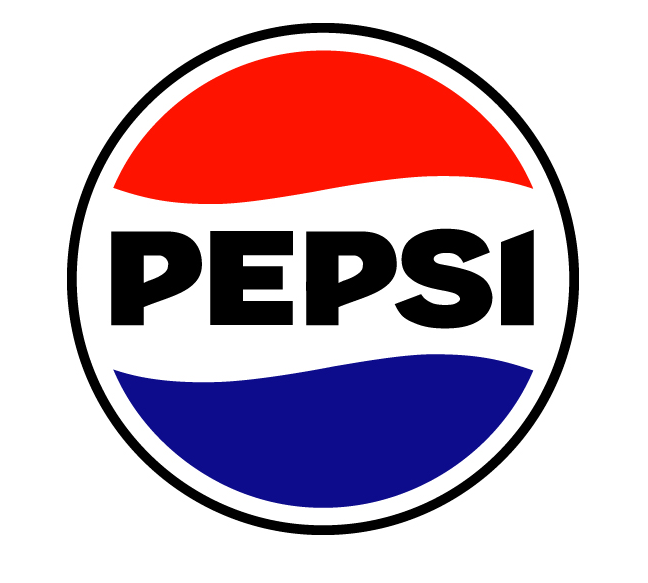


clear
clf

%------------------------- Create database ---------------------------

dataBase = cell(200, 1);

for i = 1:200
    dataBase{i} = imread(['Database_logos/' int2str(i) '.jpg']);
end

save dataBase dataBase

%------------------------- Resize database ----------------------------

numImages = numel(dataBase);

targetSize = [50, 50];

for i = 1:numImages
    currentImage = dataBase{i};
    resizedImage = imresize(currentImage, targetSize);
    dataBase{i} = resizedImage;
end

save dataBase dataBase;

%----------------------- Create color database ------------------------

colorBase = cell(200, 1);

for i = 1:200
    
    currentImage = dataBase{i};
    
    labImage = rgb2lab(currentImage);
    
    L = labImage(:, :, 1);
    a = labImage(:, :, 2);
    b = labImage(:, :, 3);
    
    colorBase{i} = struct('L', L, 'a', a, 'b', b);
end

save colorBase colorBase

%--------------------------- Query Image -----------------------------

queryImage = imread("Database_logos/32.jpg"); % Logos 
%queryImage = imread("Images/db1_01.jpg"); % Faces
%queryImage = imread("Images/night.jpg"); % Starry Night
imshow(queryImage);

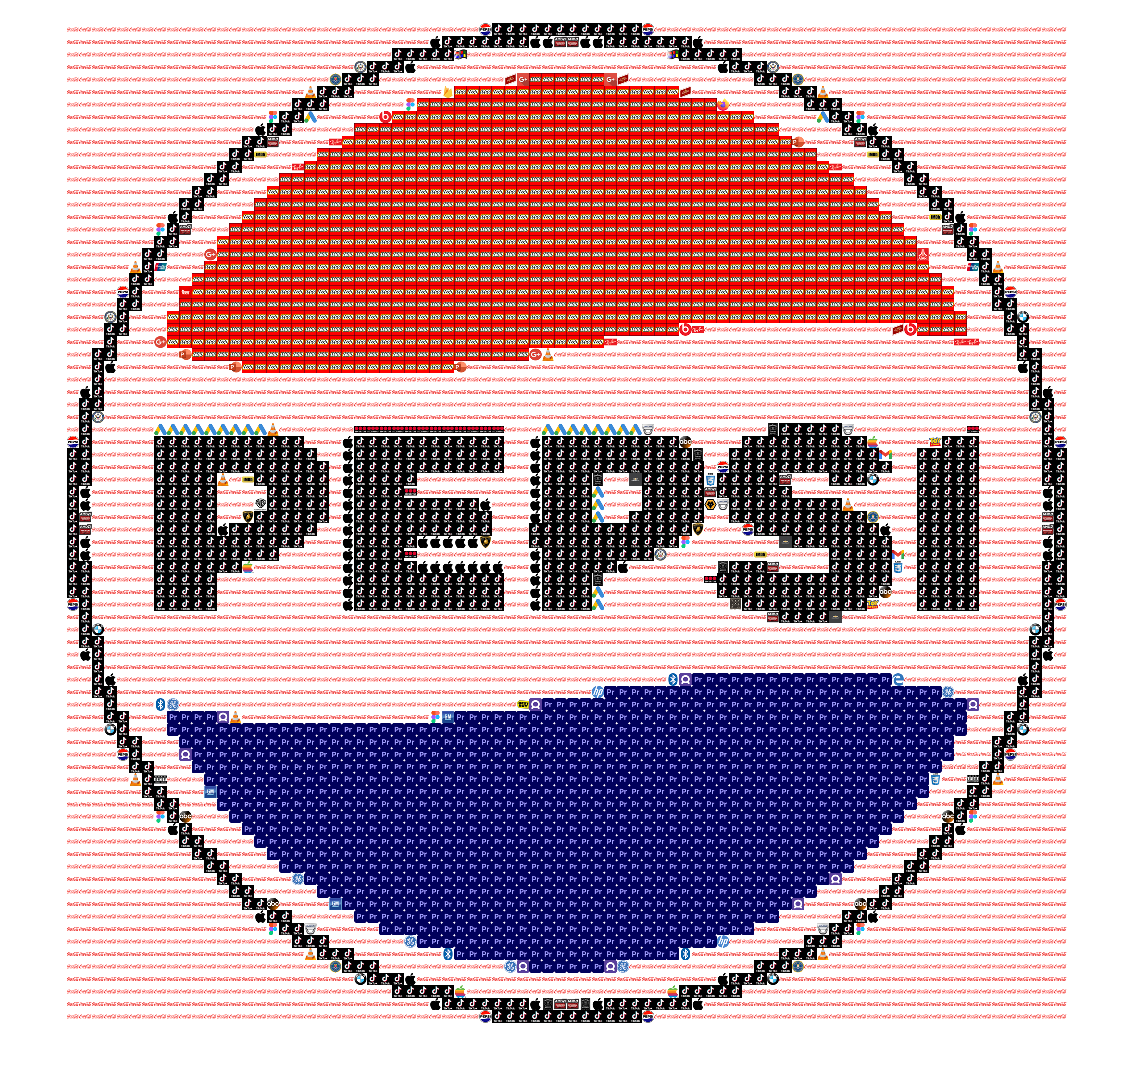


queryImage = imresize(queryImage, [2000, 2000]);

queryImageLab = rgb2lab(queryImage);

QueryColorBase = cell(1, 1);
 
L_Query = sum(sum(queryImageLab(:,:,1))); 
A_Query = sum(sum(queryImageLab(:,:,2))); 
B_Query = sum(sum(queryImageLab(:,:,3))); 
    
QueryColorBase{1} = struct('L', L_Query, 'a', A_Query, 'b', B_Query);

save QueryColorBase QueryColorBase

%-------------------------- Reproduction -----------------------------

gridSize = 25; 
numRows = size(queryImageLab, 1) / gridSize;
numCols = size(queryImageLab, 2) / gridSize;

for i = 1:numRows
    for j = 1:numCols
        
        % Grid region
        replaceRegionRows = (i-1)*gridSize+1 : i*gridSize;
        replaceRegionCols = (j-1)*gridSize+1 : j*gridSize;
        
        % LAB in current grid region
        L_Region = queryImageLab(replaceRegionRows, replaceRegionCols, 1);
        A_Region = queryImageLab(replaceRegionRows, replaceRegionCols, 2);
        B_Region = queryImageLab(replaceRegionRows, replaceRegionCols, 3);
        
        % Use median instead of mean
        currentColor = [median(L_Region(:)), median(A_Region(:)), median(B_Region(:))];

        % Varibles
        currentDiff = inf;
        bestMatchIndex = 1; 
        
        % Calculate Euclidean distance for each image
        for q = 1:200
            
            targetColor = [median(colorBase{q}.L(:)), median(colorBase{q}.a(:)), median(colorBase{q}.b(:))];
            
            distance = norm(currentColor - targetColor);
            
            if distance < currentDiff
                bestMatchIndex = q;
                currentDiff = distance;
            end   
        end

        % Resize image based on region size and place the small images. 
        Pixel_Image = imresize(colorBase{bestMatchIndex}.L, [numel(replaceRegionRows), numel(replaceRegionCols)]);
        queryImageLab(replaceRegionRows, replaceRegionCols, 1) = Pixel_Image;
        
        Pixel_Image = imresize(colorBase{bestMatchIndex}.a, [numel(replaceRegionRows), numel(replaceRegionCols)]);
        queryImageLab(replaceRegionRows, replaceRegionCols, 2) = Pixel_Image;
        
        Pixel_Image = imresize(colorBase{bestMatchIndex}.b, [numel(replaceRegionRows), numel(replaceRegionCols)]);
        queryImageLab(replaceRegionRows, replaceRegionCols, 3) = Pixel_Image;


    end
end

%-------------------------- Show images -----------------------------

rgbImage = lab2rgb(queryImageLab); 
imshow(rgbImage)